%% random formation initialization + consensus with polar distance and angle


% GRAPH/DIGRAPH #1/2
Gx=[20*rand(5,1)-10; 0]  % position x

Gx =    -0.2047
   -1.0883
    2.9263
    4.1873
    5.0937
         0


Gy=[20*rand(5,1)-10; 0] % position y

Gy =    -4.4795
    3.5941
    3.1020
   -6.7478
   -7.6200
         0


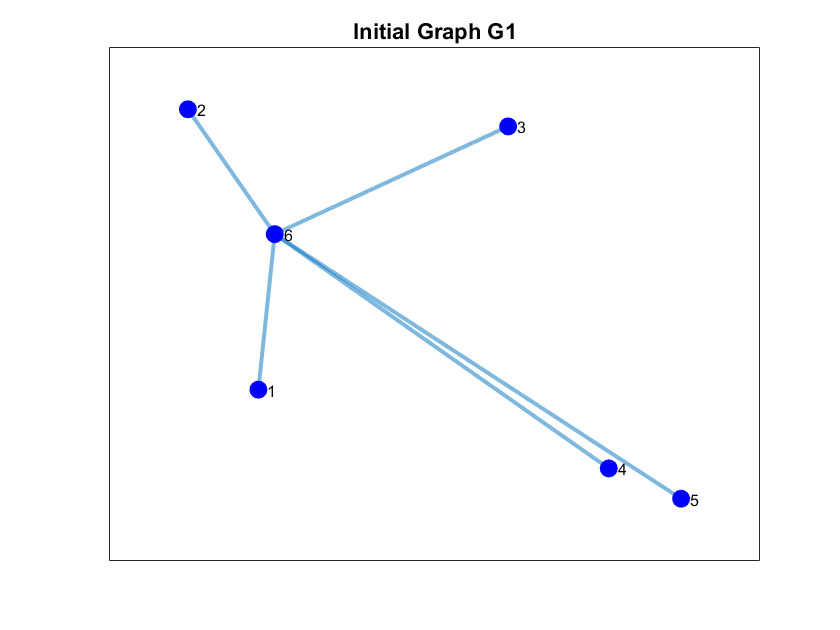


% GRAPH #1
edgesG1 = [ 1 6;
            2 6;
            3 6;
            4 6;
            5 6;];
figure; G1 = graph(edgesG1(:,1),edgesG1(:,2));
plot(G1,'XData',Gx,'YData',Gy,'MarkerSize',8,'NodeColor','b', 'LineWidth',2);
xticks([]); yticks([]); title('Initial Graph G1')

% two consensus matrices: 1 for rho (distance), 1 for theta (polar angle)

% P_rho = [1/2 0 0 0 0 1/2;
%          0 1/2 0 0 0 1/2;
%          0 0 1/2 0 0 1/2;
%          0 0 0 1/2 0 1/2;
%          0 0 0 0 1/2 1/2;
%          0 0 0 0 0 1];
% 
% P_theta = [ 0       0       0       0       0       1;
%             1/2     0       1/2     0       0       0;
%             0       1/2     0       1/2     0       0;
%             0       0       1/2     0       1/2     0;
%             1/2     0       0       1/2     0       0;
%             0       0       0       0       0       1];
%
%P_theta=eye(6);

% Polar coordinates
G_rho = [ 6*rand(5,1)+3; 0]

G_rho =     5.9902
    8.7585
    5.0423
    6.5116
    4.3429
         0


G_theta = [ 0 ; 0.628; 0.628*2; 0.628*3; 0.628*4; 0]

G_theta =          0
    0.6280
    1.2560
    1.8840
    2.5120
         0


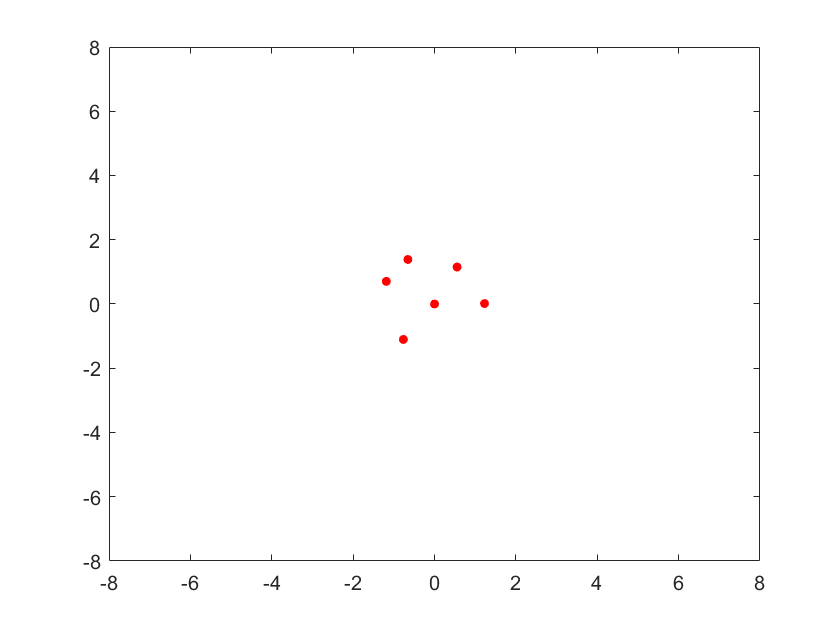

n=50;

G_rho_new = G_rho;

for i=1:n
    % Convert to cartesian coords
    Gx = [G_rho(1)*cos(G_theta(1));
        G_rho(2)*cos(G_theta(2));
        G_rho(3)*cos(G_theta(3));
        G_rho(4)*cos(G_theta(4));
        G_rho(5)*cos(G_theta(5));
        0];
    Gy = [G_rho(1)*sin(G_theta(1));
        G_rho(2)*sin(G_theta(2));
        G_rho(3)*sin(G_theta(3));
        G_rho(4)*sin(G_theta(4));
        G_rho(5)*sin(G_theta(5));
        0];
    
    plot(Gx,Gy,'or','MarkerSize',4,'MarkerFaceColor','r')
    axis([-8 8 -8 8])
    
    % P_rho defined as function of the error
    err_norm = 0.2*[(G_rho(1) - 1)/G_rho(1);
                    (G_rho(2) - 1)/G_rho(2);
                    (G_rho(3) - 1)/G_rho(3);
                    (G_rho(4) - 1)/G_rho(4);
                    (G_rho(5) - 1)/G_rho(5)];
    
    % P_theta depends on the error in angular displacements between
    % subsequent and preceding drones
    ang_err = 1.0*[G_theta(1)-G_theta(5) -G_theta(1)+G_theta(2);
                   G_theta(2)-G_theta(1) -G_theta(2)+G_theta(3);
                   G_theta(3)-G_theta(2) -G_theta(3)+G_theta(4);
                   G_theta(4)-G_theta(3) -G_theta(4)+G_theta(5);
                   G_theta(5)-G_theta(4) -G_theta(5)+G_theta(1)];
    
    ang_err = ang_err/(2*pi);    % normalization
    
    % only positive, <2pi angles
    for row=1:5
        for col=1:2
            if ang_err(row,col) > 2*pi
                ang_err(row,col) = ang_err(row,col) - 2*pi;
            end
            if ang_err(row,col) < 0
                ang_err(row,col) = abs(ang_err(row,col));
            end
        end
    end
    
    %  OXO <------- OXO --------> OXO   each drone tries to keep the same
    %  distance wrt the neighbors
    
    P_rho = [1-err_norm(1) 0             0             0             0             err_norm(1);
             0             1-err_norm(2) 0             0             0             err_norm(2);
             0             0             1-err_norm(3) 0             0             err_norm(3);
             0             0             0             1-err_norm(4) 0             err_norm(4);
             0             0             0             0             1-err_norm(5) err_norm(5);
             0             0             0             0             0             1           ];
    
    P_theta = [1   ang_err(1,1)-ang_err(1,2)   0   0   ang_err(1,2)-ang_err(1,1)   0   ;
               ang_err(2,2)-ang_err(2,1)   1   ang_err(2,1)-ang_err(2,2)   0   0   0   ;
               0   ang_err(3,2)-ang_err(3,1)   1   ang_err(3,1)-ang_err(3,2)   0   0   ;
               0   0   ang_err(4,2)-ang_err(4,1)   1   ang_err(4,1)-ang_err(4,2)   0   ;
               ang_err(5,1)-ang_err(5,2)   0   0   ang_err(5,2)-ang_err(5,1)   1   0   ;
               0   0   0   0   0   1   ];
    
    G_rho = P_rho*G_rho;
    G_theta = P_theta*G_theta;
    for j=1:4
        %theta
        if (G_theta(j) > 2*pi)
            G_theta(j) = G_theta(j)-2*pi;
        end
        %if (G_theta(5) < 2*pi)
        %        G_theta(j) = G_theta(j)+2*pi;
        %end
    end
    
    pause(0.2)
end